## Задание 2: Графики.

*Часть 1: Двумерная графика*

1. Задать вектор x с помощью оператора  двоеточие ( :  ) или непосредственно. Сформировать матрицу y с двумя столбцами, каждый из которых представляет собой некоторую элементарную функцию от x. На одном рисунке построить два графика: y1(x) и y2(x).

clc;
clear;
x = -3*pi:1/100*pi:3*pi;
y = [sin(x); cos(x)];
y = y'

y =    -0.0000   -1.0000
   -0.0314   -0.9995
   -0.0628   -0.9980
   -0.0941   -0.9956
   -0.1253   -0.9921
   -0.1564   -0.9877
   -0.1874   -0.9823
   -0.2181   -0.9759
   -0.2487   -0.9686
   -0.2790   -0.9603


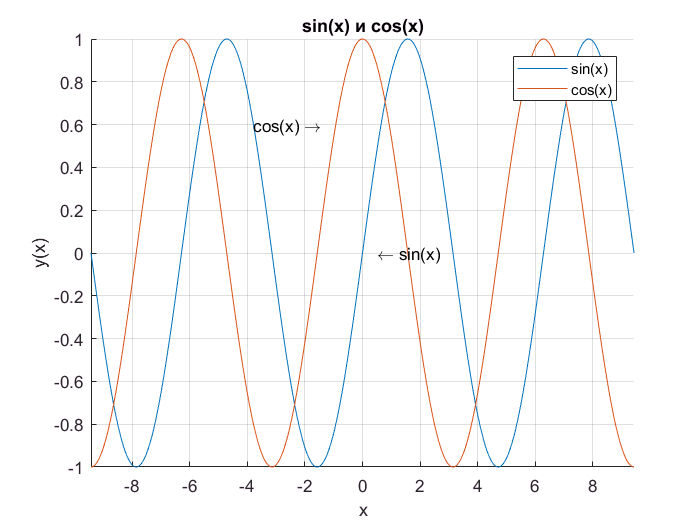

figure('Name', 'График')
grid on;
hold on;
axis([-3*pi 3*pi -1 1]);
title('sin(x) и cos(x)');
plot(x, y(:, 1));
plot(x, y(:, 2));
xlabel('x');
ylabel('y(x)');
legend('sin(x)', 'cos(x)');
text(0.5, 0, '\leftarrow sin(x)');
text(-3.8, 0.6, 'cos(x) \rightarrow');

2. Построить график заданного вектора  x  в зависимости от индекса элемента.

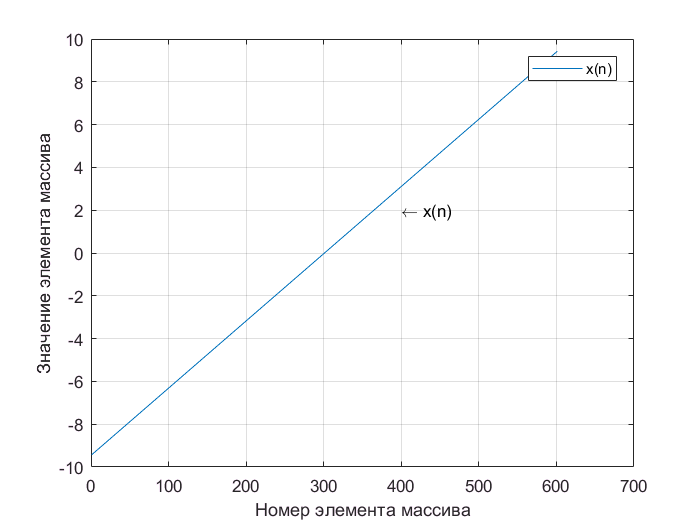

clc;
figure('Name', "x от N");
title('х от x(n)');
axis([0 length(x) -3*pi 3*pi]);
y = 1:length(x);
plot(y, x);
grid on;
xlabel('Номер элемента массива');
ylabel('Значение элемента массива');
legend('x(n)');
text(400, 2, '\leftarrow x(n)');

3. Повторить задание п.1 задавая цвет линии, тип линии, тип точек. 

Цвет линии – Желтый, Фиолетовый, Голубой, Красный, Зеленый, Синий, Белый, Черный. 

Тип линии – сплошная,  двойной пунктир, штрих-пунктир, штриховая; 

тип точки – точка; окружность; крест; плюс; звуздочка; квадрат; ромб; треугольнок (вниз); треугольник (вверх); треугольник (влево); треугольник (вправо); пятиугольник; шестиугольник. 

Попробовать все варианты, отобразить в отчете 2 понравившихся варианта.

**Вариант 1:**

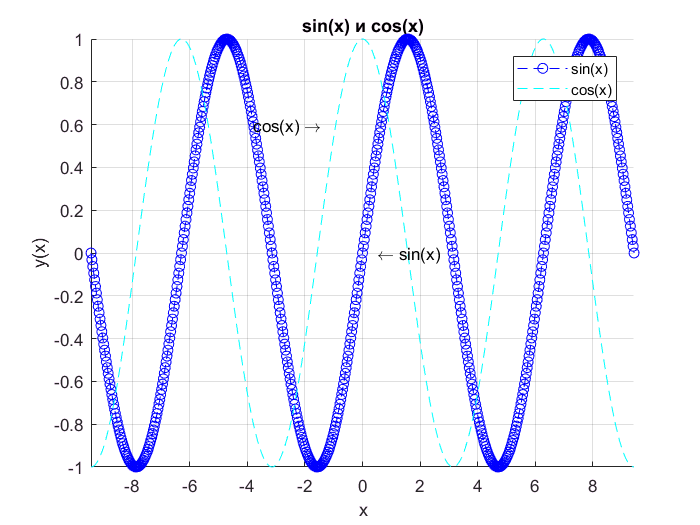

clc;
clear;
x = -3*pi:1/100*pi:3*pi;
y = [sin(x); cos(x)];
y = y';
figure('Name', 'График')
grid on;
hold on;
axis([-3*pi 3*pi -1 1]);
title('sin(x) и cos(x)');
plot(x, y(:, 1), 'b--o');
plot(x, y(:, 2), 'c--');
xlabel('x');
ylabel('y(x)');
legend('sin(x)', 'cos(x)');
text(0.5, 0, '\leftarrow sin(x)');
text(-3.8, 0.6, 'cos(x) \rightarrow');

**Вариант 2:**

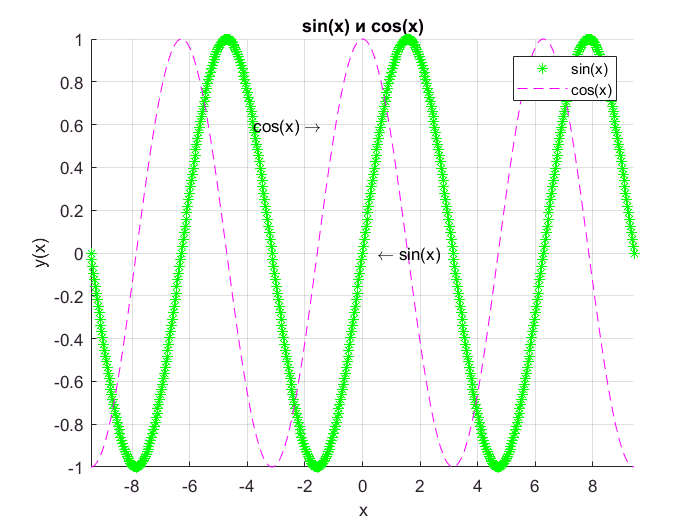

clc;
clear;
x = -3*pi:1/100*pi:3*pi;
y = [sin(x); cos(x)];
y = y';
figure('Name', 'График')
grid on;
hold on;
axis([-3*pi 3*pi -1 1]);
title('sin(x) и cos(x)');
plot(x, y(:, 1), '*', 'Color', 'g');
plot(x, y(:, 2), '--', 'Color', 'magenta');
xlabel('x');
ylabel('y(x)');
legend('sin(x)', 'cos(x)');
text(0.5, 0, '\leftarrow sin(x)');
text(-3.8, 0.6, 'cos(x) \rightarrow');

4. Задать некоторую функцию вектора x. Построить столбцовую диаграмму функции с помощью оператора bar. Изменить количество меток по оси x  и подписи к ним.

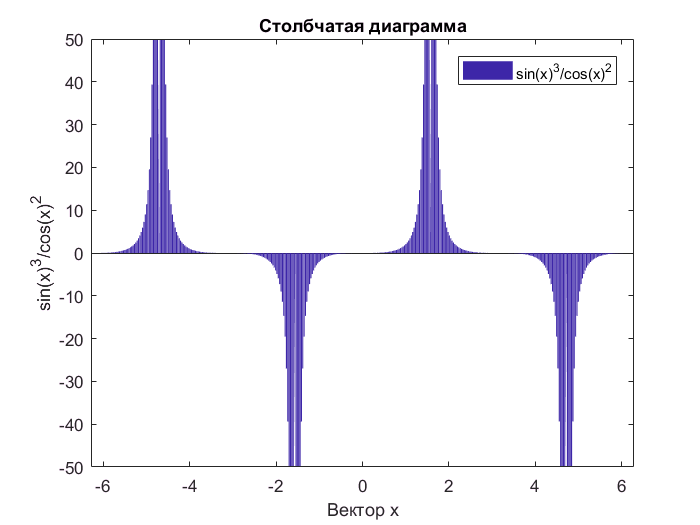

clc;
y = sin(x).^3 ./ cos(x).^2;
figure('Name', 'Столбцы');
grid on;
bar(x, y);
axis([-2*pi 2*pi -50 50]);
title('Столбчатая диаграмма');
xlabel('Вектор x');
ylabel('sin(x)^3/cos(x)^2');
legend('sin(x)^3/cos(x)^2');

5. Задать функцию вектора x. Построить ступенчатую функцию с помощью оператора **stairs**. Изменить пределы изображения по осям, цвет и толщину линий.

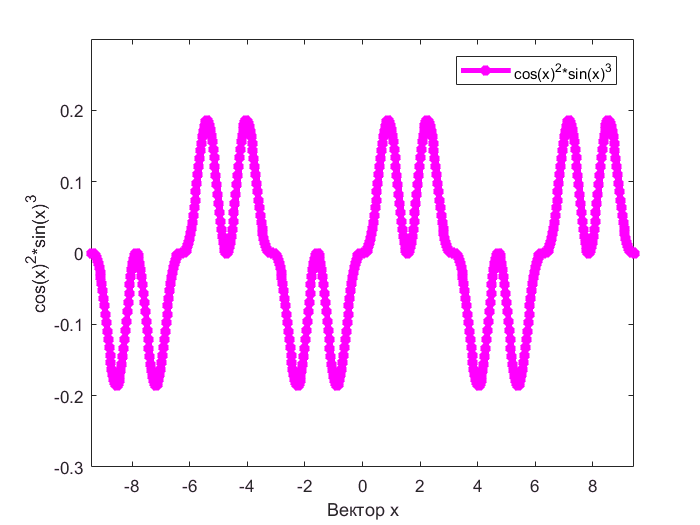

clc;
y = cos(x).^2 .* sin(x).^3;
figure('Name', 'Stairs');
grid on;
title('Ступенчатая функция');
stairs(x, y, 'LineWidth', 3, 'Marker', '*', 'Color', 'magenta');
axis([-3*pi 3*pi -0.3 0.3]);
xlabel('Вектор x');
ylabel('cos(x)^2*sin(x)^3');
legend('cos(x)^2*sin(x)^3');

6. Задать функцию вектора x. Построить функцию с вертикальной штриховкой с помощью оператора **stem**. Изменить фон графика.

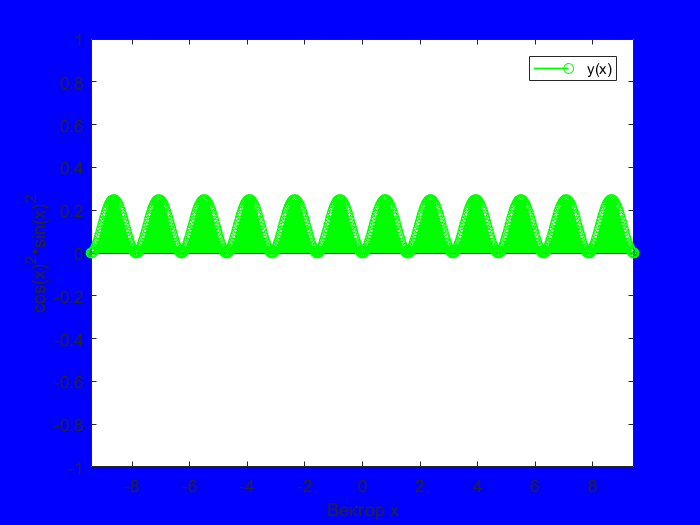

clc;
y = cos(x).^2 .* sin(x).^2;
figure('Name', 'Stem', 'Color', 'b');
grid on;
title('Функция с штриховкой');
stem(x, y, 'LineWidth', 1, 'Color', 'g');
axis([-3*pi 3*pi -1 1]);
xlabel('Вектор x');
ylabel('cos(x)^2*sin(x)^2');
legend('y(x)');

7. Задать функцию вектора x. Сформировать функцию-ошибку с помощью случайной матрицы rand, имеющей размерность вектора x (size(x)). Построить  график функции-ошибки с помощью оператора **errorbar****.**

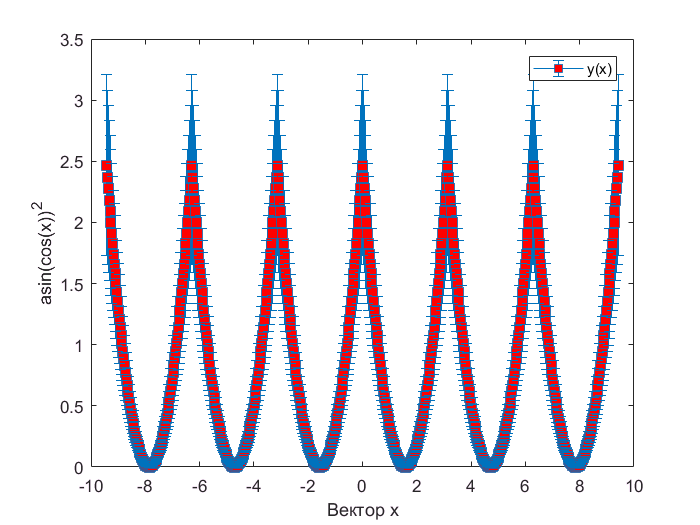

clc;
y = asin(cos(x)).^2;
err = 0.3*y;
figure('Name', 'Errorbar');
title('Функция с погрешностью');
grid on;
errorbar(x, y, err, '-s', 'MarkerSize', 8, 'markerFaceColor', 'r');
xlabel('Вектор x');
ylabel('asin(cos(x))^2');
legend('y(x)');

8. Построить график функции в полярных координатах в виде ромашки с 7 лепестками. 

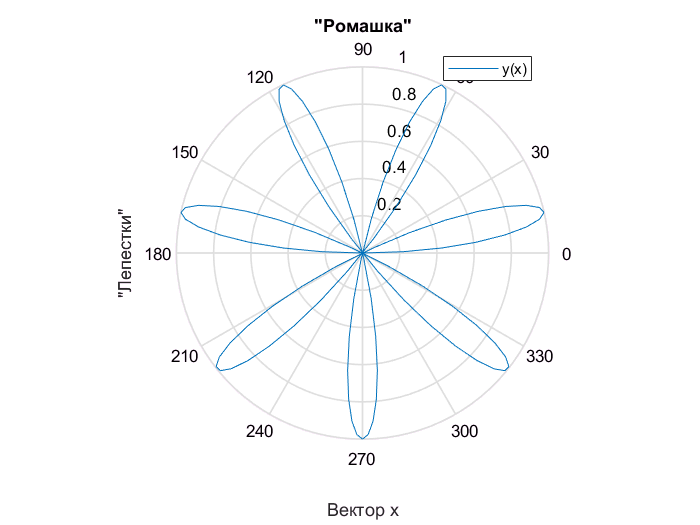

figure('Name', 'Полярные координаты');
polar(x, sin(7*x));
title('"Ромашка"');
xlabel('Вектор x');
ylabel('"Лепестки"');
legend('y(x)');

9. Построить графики экспоненты и квадратичной зависимости в логарифмических и полулогарифмических координатах.

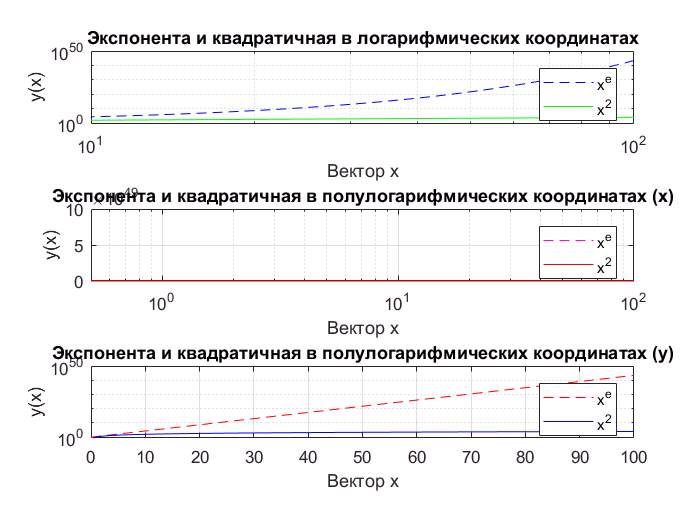

figure('Name', 'Логарифмические координаты');
x = 0:0.5:100;
subplot(3, 1, 1);
loglog(x, exp(x), '--', 'Color', 'b');
grid on;
hold on;
title('Экспонента и квадратичная в логарифмических координатах');
loglog(x, x.^2, 'Color', 'g');
xlabel('Вектор x');
ylabel('y(x)');
legend('x^e', 'x^2');
axis([10 100 0 10^50]);
subplot(3, 1, 2);
semilogx(x, exp(x), '--', 'Color', 'm');
grid on;
hold on;
title('Экспонента и квадратичная в полулогарифмических координатах (x)');
semilogx(x, x.^2, 'Color', 'r');
xlabel('Вектор x');
ylabel('y(x)');
legend('x^e', 'x^2');
axis([0 100 0 10^50]);
subplot(3, 1, 3);
semilogy(x, exp(x), '--', 'Color', 'r');
grid on;
hold on;
title('Экспонента и квадратичная в полулогарифмических координатах (y)');
semilogy(x, x.^2, 'Color', 'b');
xlabel('Вектор x');
ylabel('y(x)');
legend('x^e', 'x^2');
axis([0 100 0 10^50]);

10. Построить гистограммы.   Cформировать случайный вектор  *x* с помощью оператора **randn****(****N****,1**), и случайный вектор   *y**=2+* **randn****(****M****,1**),   N, M >500. Построить в одних осях гистограммы с помощью функции histogram(x), histogram(y)  и нормализовать для сравнения результатов.

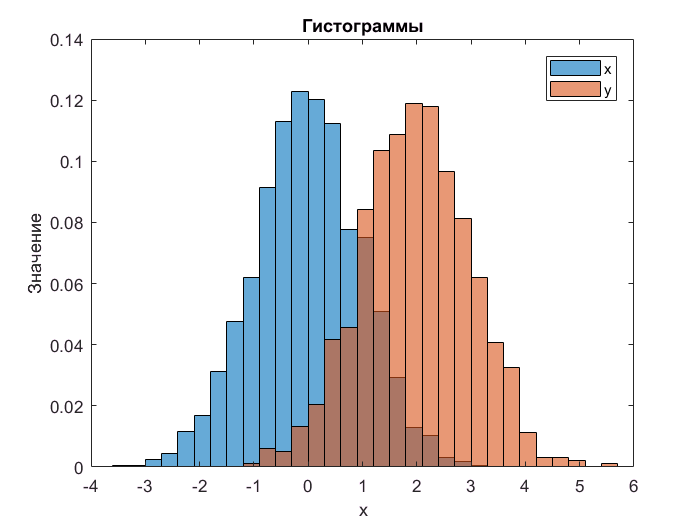

x = randn(1532, 1);
y = 2 + randn(984, 1);
figure('Name', 'Гистограмма');
h1 = histogram(x);
hold on
h2 = histogram(y);
h1.Normalization = 'probability';
h1.BinWidth = 0.3;
h2.Normalization = 'probability';
h2.BinWidth = 0.3;
legend('x', 'y');
xlabel('x');
ylabel('Значение');
title('Гистограммы');